# TITLE: Signal Modulation and Detection in an AWGN Channel with Phase Noise

Authors: Fernando Guiomar [guiomar@av.it.pt](http://guiomar@av.it.pt) 

Last Update: 08/11/2019

## Initialization

clear;
clear global;
close all;
rng(1)
clc;

% Load Libraries:
addpath(genpath('../../../'));

global PROG;
PROG.showMessagesLevel = 2;
initProg();

Current Date: 29-Jun-2023 03:45:58


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                      PROGRAM INITIALIZATION                      %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


RGB = fancyColors();

## Input Parameters

SIG.M = 256;                 % QAM constellation size
SIG.symRate = 60e9;         % total symbol-rate of the signal
SIG.modulation = 'QAM';     % modulation type [QAM/PAM]
SIG.rollOff = 0.1;          % roll-off factor
SIG.nPol = 1;               % number of polarizations
SIG.nSyms = 2^17;           % total number of simulated symbols
nSpS = 2;                   % number of samples per symbol
laserLW = 500e3;              % laser linewidth [Hz]

SNR_dB = ber2snr(1e-2,SIG.M);   % SNR in dB

## Set Transmitter Parameters

#### Signal Parameters:

TX.SIG = setSignalParams('symRate',SIG.symRate,'M',SIG.M,...
    'nPol',SIG.nPol,'nBpS',log2(SIG.M),'nSyms',SIG.nSyms,...
    'roll-off',SIG.rollOff,'modulation',SIG.modulation);

#### Modulation Parameters:

TX.QAM = QAM_config(TX.SIG);

#### Bit Parameters:

TX.BIT.source = 'randi';
TX.BIT.seed = 1;

#### Pulse Shaping Filter Parameters:

TX.PS.type = 'RRC';
TX.PS.rollOff = TX.SIG.rollOff;
TX.PS.nTaps = 128;

#### DAC Parameters:

TX.DAC.RESAMP.sampRate = nSpS*TX.SIG.symRate;

#### LASER Parameters:

TX.LASER.linewidth = laserLW;

## Set DSP Parameters

%% Matched-Filter:
DSP.MF.type = 'RRC';
DSP.MF.rollOff = TX.SIG.rollOff;

%% Carrier-Phase Estimation:
DSP.CPE.method = 'BPS';
DSP.CPE.decision = 'QPSKpartition';
DSP.CPE.QAM_classes = 'all';
DSP.CPE.nTaps = 49;
DSP.CPE.nTestPhases = 64

DSP = struct with fields:
     MF: [1×1 struct]
    CPE: [1×1 struct]




%% Demapper:
DSP.DEMAPPER.normMethod = 'MMSE';

## Generate Tx Bits

TX.BIT.txBits = Tx_generateBits(SIG.nSyms,TX.QAM.M,TX.QAM.nPol,TX.BIT);

## Generate Transmitted Symbols

[S.tx,TX.BIT.txSyms] = Tx_QAM(TX.QAM,TX.BIT.txBits);

#### Plot Transmitted Constellation Symbols:

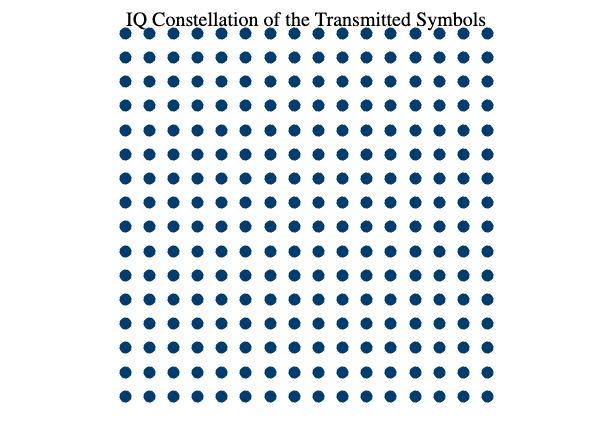

scatterPlot(S.tx,'markersize:sig',20);
title('IQ Constellation of the Transmitted Symbols','interp','latex')

## Pulse Shaping

[S.txSC,TX.PS] = pulseShaper(S.tx,nSpS,TX.PS);

#### Plot Pulse Shaping Taps

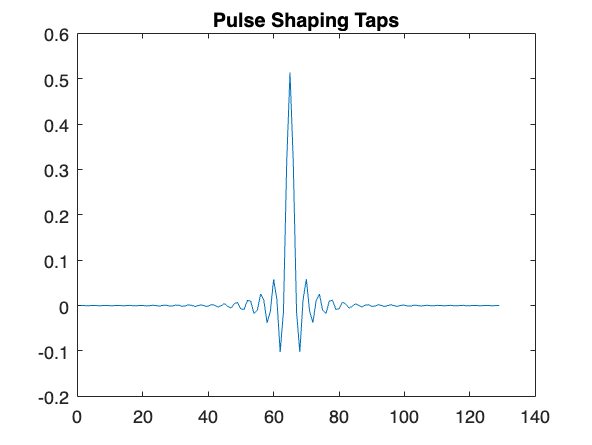

figure();
plot(TX.PS.W);
title('Pulse Shaping Taps')

#### Plot Signal Spectrum

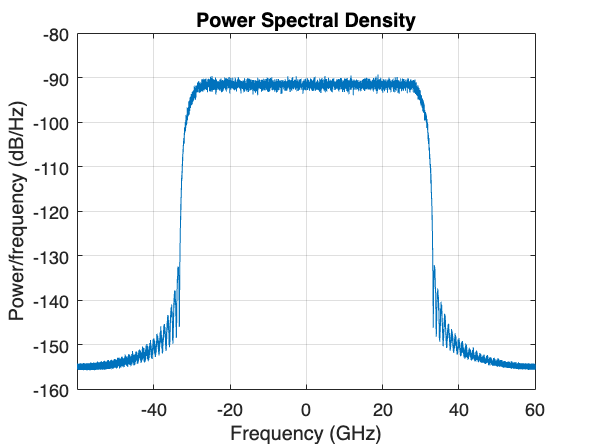

figure();
pwelch(S.txSC(1,:),1e4,[],[],TX.DAC.RESAMP.sampRate,'centered')

## Digital-to-Analog Converter

Fs_SC = nSpS * SIG.symRate;
[S.txSC,TX.DAC] = Tx_DAC(S.txSC,TX.DAC,Fs_SC);

## Apply Laser

nSamples = size(S.tx,2) * nSpS;
[Scw,TX.LASER] = laserCW(TX.LASER,Fs_SC,nSamples);
nPol = size(S.txSC,1);
if nPol == 2
    Scw = Scw/sqrt(2);      % divide CW power by 2 if dual-pol
end
for n = 1:nPol
    S.txSC(n,:) = Scw.*S.txSC(n,:);
end

#### Plot Laser Phase Noise

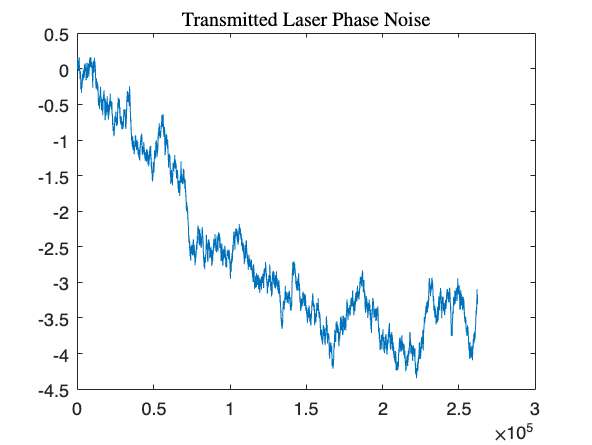

figure();
plot(TX.LASER.phaseNoise)
title('Transmitted Laser Phase Noise','interp','latex')

## Set SNR

S.rx = setSNR(S.txSC,SNR_dB,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Apply Matched Filter

S.rx = LPF_apply(S.rx,DSP.MF,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Downsample to 1 Sample/Symbol

S.rx_1sps = S.rx(1:nSpS:end)*nSpS;

## Plot Received Constellation Symbols

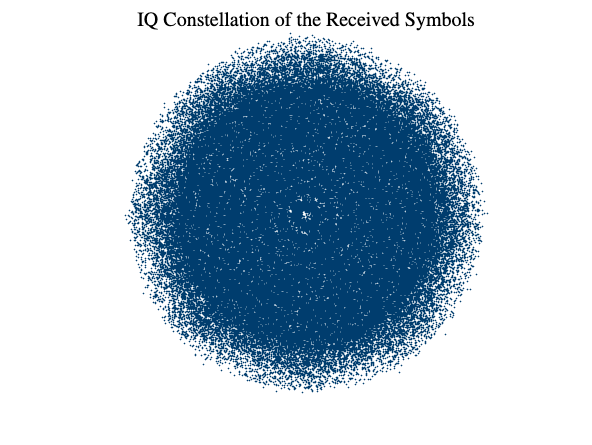

scatterPlot(S.rx_1sps);
title('IQ Constellation of the Received Symbols','interp','latex')

## Apply CPE

C = TX.QAM.IQmap;

[S.rx_1sps,DSP.CPE] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE,C,1);

## Plot Laser Phase Noise

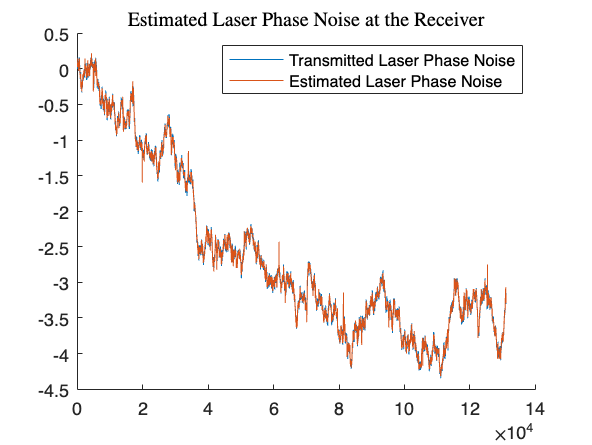

figure();
hold on;
plot(TX.LASER.phaseNoise(1:nSpS:end))
plot(DSP.CPE.phi)
legend('Transmitted Laser Phase Noise','Estimated Laser Phase Noise');
title('Estimated Laser Phase Noise at the Receiver','interp','latex');

## Resolve Phase Ambiguity

phaseShift = mean(TX.LASER.phaseNoise(1:nSpS:end) - DSP.CPE.phi);
% S.rx_1sps = S.rx_1sps * exp(1j*phaseShift);

## Apply Symbol Demapper

[DSP.DEMAPPER,S.tx] = symDemapper(S.rx_1sps,S.tx,C,DSP.DEMAPPER);

## Calculate Bit-Error Ratio (BER)

[BER,errPos] = BER_eval(DSP.DEMAPPER.txBits,DSP.DEMAPPER.rxBits);

## Calculate Error Vector Magnitude (EVM)

EVM = EVM_eval(S.rx_1sps,S.tx);

## Plot Constellation after Demapping

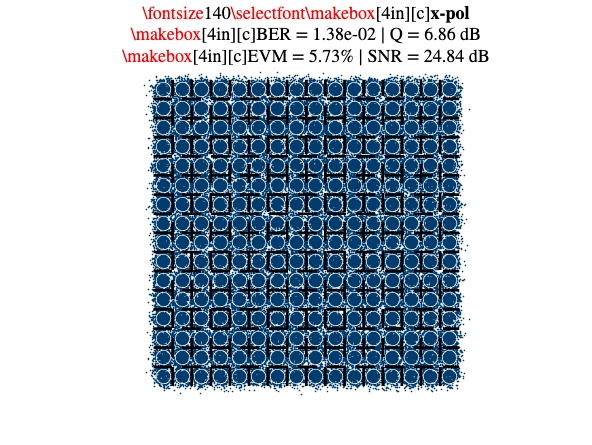

scatterPlot(S.rx_1sps,'BER',BER,'EVM',EVM,'const',DSP.DEMAPPER.C);

% title('IQ Constellation of the Received Symbols After Demapper')

## Exit PROG

exitProg();



Total Elapsed Time: 13.2517 [s]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                               END                                %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
